% Load face images from a folder
imageDir = 'Faces/';
testimages = dir(fullfile(imageDir, 'db1*.jpg'));
numImages = numel(testimages);

% Read images into a cell array
faceData = cell(1, numImages);
for i = 1:numImages
    % Load your image
    img = im2double(imread(fullfile(imageDir, "db1_" + i + ".jpg")));
    [eye1, eye2] = findEyes(img);
    faceData{i} = faceNormalization(img, eye1, eye2);
end

Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds. Index must not exceed 1.



% Flatten each image into a vector
faceVectors = cellfun(@(x) x(:), faceData, 'UniformOutput', false);
% Combine faceVectors to form X (each row represents an image)
numPixels = numel(faceVectors{1}); % Number of pixels in each image

X = zeros(numPixels, numImages);

for i = 1:numImages
    X(:, i) = faceVectors{i}';
end

zeros()

ans = 0


mean_face = mean(X, 2)

mean_face =     0.1131
    0.1200
    0.1250
    0.1260
    0.1151
    0.1032
    0.0962
    0.1012
    0.1052
    0.1151


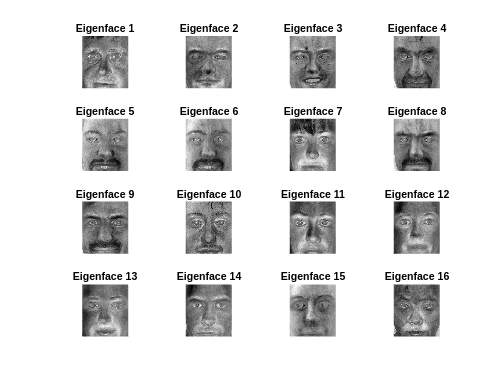


A = X - mean_face;

V = A'*A;

E = eig(V);

U = A*V;

[E, order] = sort(diag(E), 'descend');
U = U(:,order);
[width, ~] = size(faceData{1});
figure;
for i = 1:16
   eigenface = reshape(U(:,i), width, []);
   subplot(4, 4, i);
   imshow(eigenface, []);
   title(['Eigenface ', num2str(i)]);
end


W = U'*A;

save("traind__model", 'mean_face', 'W', 'U');


